%  多元回归分析
%  输入各种自变量数据
x1 = [5.5, 2.5, 8, 3, 3, 2.9, 8, 9, 4, 6.5, 5.5, 5, 6, 5, 3.5, 8, 6, 4, 7.5, 7]';
x2 = [31, 55, 67, 50, 38, 71, 30, 56, 42, 73, 60, 44, 50, 39, 55, 70, 40, 50, 62, 59]';
x3 = [10, 8, 12, 7, 8, 12, 12, 5, 8, 5, 11, 12, 6, 10, 10, 6, 11, 11, 9, 9]';
x4 = [8, 6, 9, 16, 15, 17, 8, 10, 4, 16, 7, 12, 6, 4, 4, 14, 6, 8, 13, 11]';
y = [79.3, 200.1, 163.1, 200.1, 146.0, 177.7, 30.9, 291.9, 160, 339.4, 159.6, 86.3, 237.5, 107.2, 155, 201.4, 100.2, 135.8, 223.3, 195]';
X=[ones(size(x1)),x1,x2,x3,x4];
[b,bint,r,rint,stats]=regress(y,X)% 回归分析

b =   191.9906
   -0.7751
    3.1718
  -19.6849
   -0.4494


bint =   103.1866  280.7946
   -7.1474    5.5972
    2.0634    4.2802
  -25.1686  -14.2012
   -3.7276    2.8288


r =    -6.3088
   -4.2260
    5.0635
   -3.1701
    0.0269
    6.6185
  -10.2294
   32.1836
   -2.8287
   26.5217


rint =   -56.5100   43.8924
  -51.7978   43.3459
  -40.5391   50.6662
  -49.7192   43.3789
  -44.3792   44.4331
  -33.2139   46.4509
  -53.1383   32.6796
   -9.9179   74.2851
  -52.7738   47.1163
  -17.9441   70.9875


stats =     0.9034   35.0555    0.0000  644.5831


Q=r'*r

Q = 9.6687e+03

sigma=Q/18

sigma = 537.1526

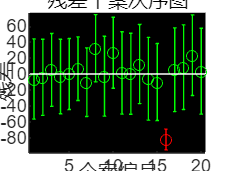

rcoplot(r,rint);